# Analyzing color histogram using eigenfaces algorithm 

Normalize matrix A by making a matrix by repeating a column vector that contains the sum of each row, and subtracting the resulting matrix from A. 

A1 = training_data

A1 =         2242        8463         273        8986        8592        2425        1610        1916         666         117        9320         595        1973       33246        9857       12435        9215       35565       18756        4849        5230         474         550        1819         299          78        4878          37           0         364          77         113         137         105           0        1326          73         329          31          12
         828        1348          86         780        1710         960         568         376         233          70        1749         272        1229         884        1516        1840        2386        1091        4010        1317         836         178         127        2113          54          45        1355          10           0          42          42          32          26          38           0         230          11          50           9           4
         875         358         

A = A1 - repmat((sum(A1,2)./40),1,40);
clear A1

Find decomposition (basically Eigenvectors and eigenvalues) of covariance matrix

U is a matrix of the eigenvalues (106x106)

S is variance in direction of egienvector s^2 are eigenvalues (106x106)

[U,S,V] = svd(transpose(A)*A);

Find U with equation ui = A*vi

 U1 (65536x106) 

U1 = (A*V);
clear U
clear S
clear V

Determine which eigenvectors from U are most important (which have the largest eigenvalues, but the first few have to do with lighting, so dispose of those), and throw out all the unnecessary eigenvectors and values. 

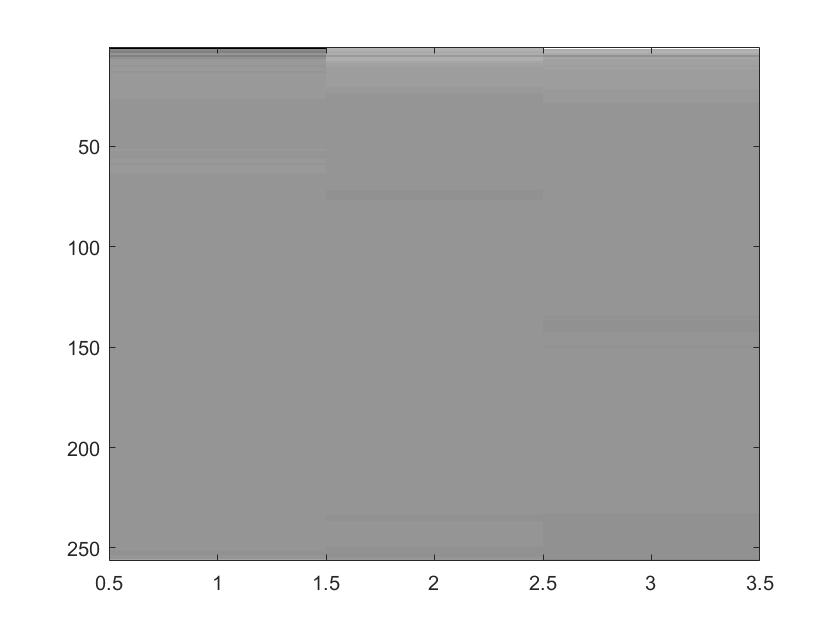

U20 = U1(:,4:18); % extract 20 entries
imagesc(reshape(U20(:,1), 256, 3)); colormap('gray') %display an eigenface

Then find out how much of each eigenvector is used to represent each face (find weights).

Weights = Transpose(U)*Image

Wtrain = transpose(U20)*A;

## When given a new face, find the weights and compare those to all existing weights 

Reshape and normalize in the same way as with the training data

Atest = test_data

Atest =         6123        5041       13493         580        3753        9812         821        7020       10990         150        2111         445        2365          20       13358       35282        2474           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
        1022        1159        1671         120        1145        1579         138        1232        6052         284         471         160         880          44        1882        1709         430           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
        1334         219        1407         138        1305        1306         172        1209        1722         143         545         158         893          21        1414         724         535           0      


Wtest = transpose(U20)*Atest;

## Run for all faces in test set and determine accuracy

Change number of eigenvectors and run again

U20 = U1(:,4:18)

U20 = 	1.0e+04 *

   -1.1996    0.3805   -0.0279    0.0634    0.1048   -0.1710   -0.0110   -0.0229   -0.0771    0.0695    0.0346   -0.0075    0.0017   -0.0081   -0.0135
   -0.1076    0.3089   -0.1213    0.0002    0.0135    0.0813    0.0967    0.0280   -0.0161   -0.2039   -0.0768    0.0560   -0.0096   -0.0422    0.0680
   -0.1646    0.3354   -0.1219    0.0247    0.0225    0.0577    0.0774    0.0056    0.0021   -0.1162   -0.0394    0.0593    0.0047    0.0743   -0.0054
   -0.0100    0.3171   -0.1091    0.0159    0.0167   -0.0518    0.0152   -0.0515    0.2135    0.0123   -0.0119    0.0403   -0.0216    0.0530    0.0333
   -0.1452   -0.1428    0.0890   -0.0116   -0.0087   -0.0554   -0.0080   -0.0400    0.0785   -0.0663   -0.0300   -0.0059   -0.0350   -0.0317    0.0519
   -0.0286    0.1608   -0.0424    0.0076    0.0085   -0.0268    0.0026   -0.0317    0.0999   -0.0092   -0.0096    0.0020   -0.0181    0.0072    0.0097
    0.0251    0.1400   -0.0341    0.0014    0.0060   -0.0260    0.0060   -0.

long_avgs = [long_avg_romance long_avg_scifi]

long_avgs =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


long_avgs_eig = (long_avgs.'*U20).'

long_avgs_eig = 	1.0e+07 *

   -0.7639   -0.4633
   -1.1817    0.8999
    0.4590    0.8688
   -2.4319   -2.8753
   -1.6135   -2.1323
   -0.5594   -0.2053
   -0.1509    0.5345
    1.1681   -1.3224
   -0.7018    0.2937
    1.0140   -0.9428


avg_tags = [0 1]

avg_tags =      0     1


Wtest = transpose(U20)*Atest;

num_true = 0;
num_false = 0;
tagged_false = 0;
tagged_false_list = [];
false_list = [];
for n = 1:32
    Wn = Wtest(:,n);
    WL = zeros(1,2);
    for j = 1:2
       WL(j) = WL(j) + sum(abs(Wn-long_avgs_eig(:,j)));
    end
    [M,I] = min(WL);
    if sum(abs(Wtrain(:,j)-Wn)) > 350000000
       tagged_false = tagged_false + 1;
       tagged_false_list = [tagged_false_list,n];
    end
    if avg_tags(I) == test_tags(n)
        num_true = num_true+1;
    else
        num_false = num_false+1;
        in = [I,n];
        false_list = [false_list, n];
    end
end

disp("Number correct: "+ num_true)

Number correct: 28


disp("Number incorrect: "+ num_false)

Number incorrect: 4


disp("Percentage correct: "+num_true/(num_false+num_true)*100)

Percentage correct: 87.5


disp("Tagged False: "+tagged_false)

Tagged False: 10


false_list = sort(false_list)

false_list =     14    15    16    17


for j = (size_false_list(:,2))

    imagesc(grayfaces_train(:,:,false_list(j-1))); colormap('gray')

    y_train.name(j)

    imagesc(grayfaces_test(:,:,n)); colormap('gray')

    y_test.name(n)

end